# Introduction to motional averaging in EPR

from T.Prisner 3.7.2020

clear;

Anisotropic interaction in EPR (A-Tensor, g-Tensor or ZFS-Tensor)

lead to a orientation dependent shift of the Larmor Resonance Frequency $\Delta \omega$ of the molecule.

If the molecule rotates with a correlation time $\tau_c$ which is faster than the 

maximum difference in Larmor-Frequencies given by the anisotropic interaction $\tau_c <<\Delta \omega \;\;$

the contribution of this anisotropic interaction to the spectra disappears and 

only the average value $\left\langle \bar{\omega_L } \right\rangle =\int \omega_L$ (over all orientations) shows up in the spectra.

We say this interaction is **averaged out.**

Let us consider as an example a radical with an unpaired electron spin S=1/2 

coupled to a single proton spin with I=1/2. The hyperfine coupling should consist of 

a isotropic part (Fermi-Contact interaction) which describes the overlap of the electron

spin orbital with the proton nucleus and an anisotropic part (Dipol-Dipol interaction) which 

describes the distance distribution of the electronic orbital to the nuclear spin.

The parameters of the spin systems can be described in** EasySpin** by:

Sys.g=2.0056;
Sys.Nucs='1H';
Aiso=10;                     % isotropic hf coupling in MHz
Aaniso=5*[-0.5 -0.5 1];      % anisotropic hf coupling in MHz
Sys.A=Aiso+Aaniso;
Sys.lw=0.01;                  % Lorenzian Linewidth in mT

The experimental parameters are:

Exp.mwFreq=9.5;              % MW frequency in GHz
CenterField=338.42;             % Center field in mT
FieldRange=0.8;               % Field Range in mT
Exp.CenterSweep=[CenterField,FieldRange];
Exp.nPoints=5000;            % Number of Data points
Exp.Harmonic=0;              % 0: Absorption spectra 1: first derivative as usually recorded in cw-EPR

EasySpin calculates the static powder spectra solving the spin Hamiltionian (pepper function):

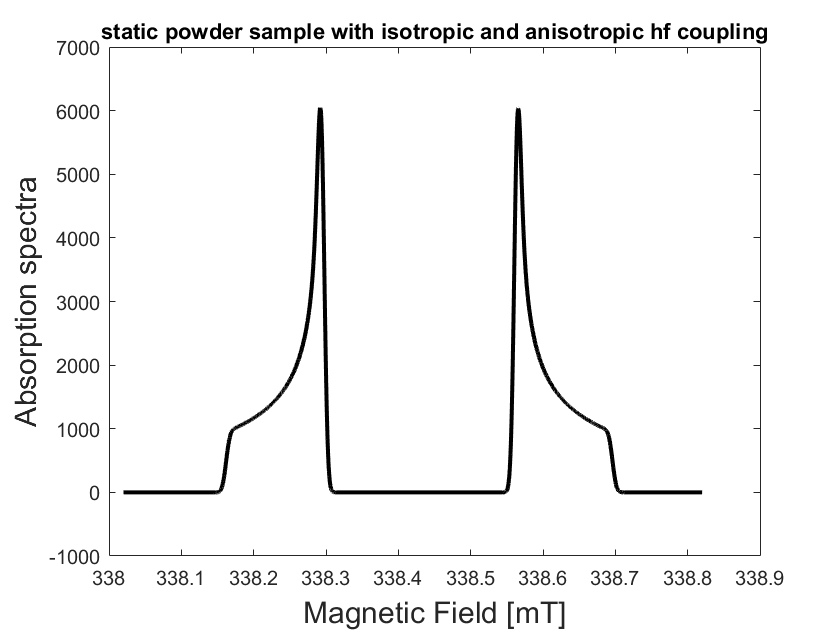

[B,spectrumPowder]=pepper(Sys,Exp);    
plot(B,spectrumPowder,'k','LineWidth',2)
xlabel('Magnetic Field [mT]','FontSize',15)
ylabel('Absorption spectra','FontSize',15)
title('static powder sample with isotropic and anisotropic hf coupling')

EasySpin calculates the motional averaged spectra using the stochastic Liouville Equation (chili function):

We do this for 3 different rotational correlation times:

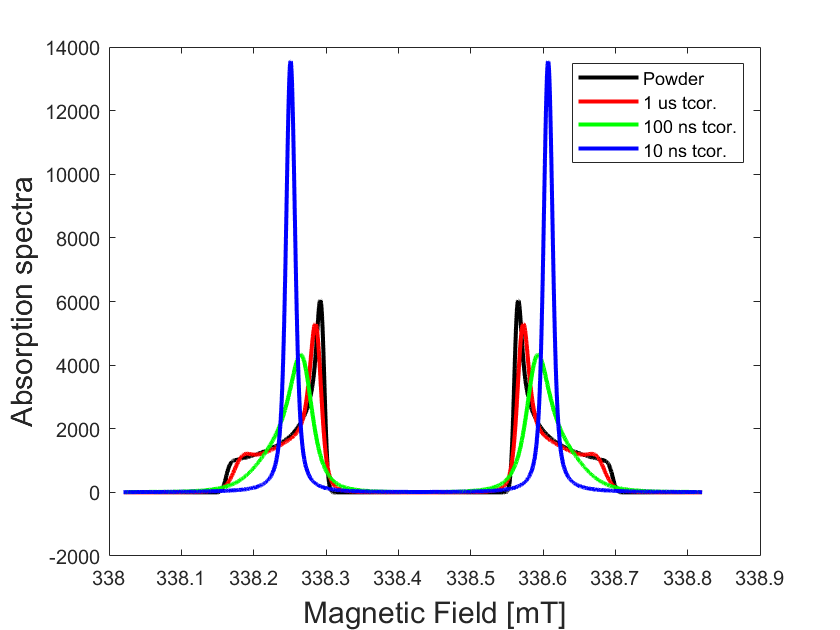

Sys.tcorr=1000e-9;              % rotational correlation time in s
spectrumRot1=chili(Sys,Exp);
Sys.tcorr=100e-9;              % rotational correlation time in s
spectrumRot2=chili(Sys,Exp);
Sys.tcorr=10e-9;              % rotational correlation time in s
spectrumRot3=chili(Sys,Exp);
plot(B,spectrumPowder,'k',B,spectrumRot1,'r',B,spectrumRot2,'g',B,spectrumRot3,'b','LineWidth',2)
xlabel('Magnetic Field [mT]','FontSize',15)
ylabel('Absorption spectra','FontSize',15)
legend('Powder','1 us tcor.','100 ns tcor.','10 ns tcor.')

If the coupling strength is a factor of 10 larger, 10 times faster correlation times are needed for averaging 

(recognize that there is a different field range!):

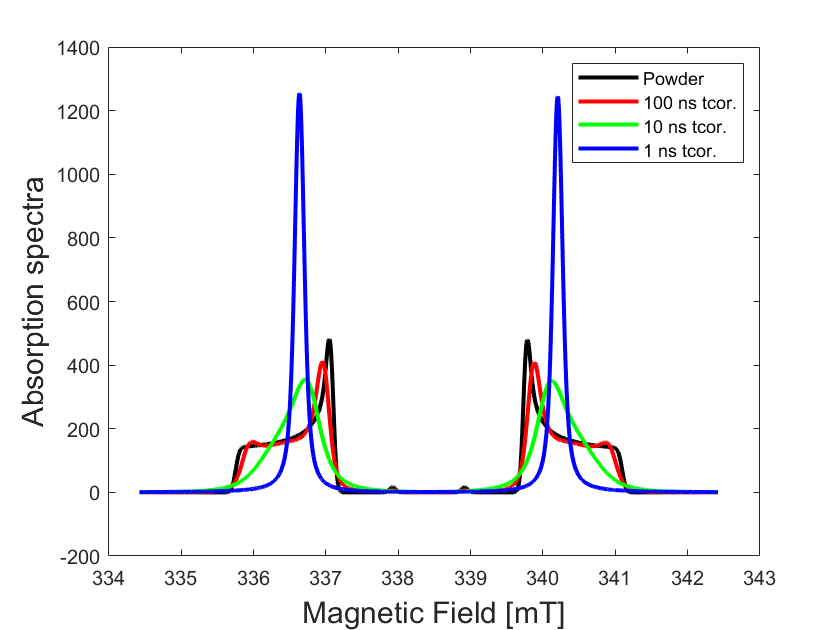

Aiso=100;                     % isotropic hf coupling in MHz
Aaniso=50*[-0.5 -0.5 1];      % anisotropic hf coupling in MHz
Sys.A=Aiso+Aaniso;
Sys.lw=0.1;                  % Lorenzian Linewidth in mT
FieldRange=8;               % Field Range in mT
Exp.CenterSweep=[CenterField,FieldRange];
[B,spectrumPowder]=pepper(Sys,Exp);    
Sys.tcorr=100e-9;              % rotational correlation time in s
spectrumRot1=chili(Sys,Exp);
Sys.tcorr=10e-9;              % rotational correlation time in s
spectrumRot2=chili(Sys,Exp);
Sys.tcorr=1e-9;              % rotational correlation time in s
spectrumRot3=chili(Sys,Exp);
plot(B,spectrumPowder,'k',B,spectrumRot1,'r',B,spectrumRot2,'g',B,spectrumRot3,'b','LineWidth',2)
xlabel('Magnetic Field [mT]','FontSize',15)
ylabel('Absorption spectra','FontSize',15)
legend('Powder','100 ns tcor.','10 ns tcor.','1 ns tcor.')

If the coupling exist to a nitrogen (14N I=1) nucleus instead of the proton (1H I=1/2) there are three lines with the center line without hf coupling

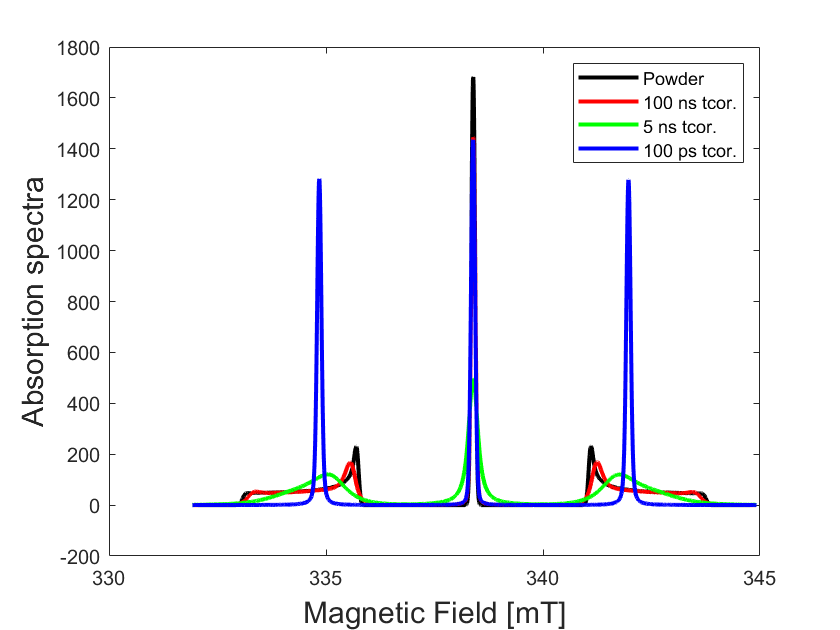

Sys.Nucs='14N';
FieldRange=13;               % Field Range in mT
Exp.CenterSweep=[CenterField,FieldRange];
[B,spectrumPowder]=pepper(Sys,Exp);    
Sys.tcorr=100e-9;              % rotational correlation time in s
spectrumRot1=chili(Sys,Exp);
Sys.tcorr=5e-9;              % rotational correlation time in s
spectrumRot2=chili(Sys,Exp);
Sys.tcorr=0.1e-9;              % rotational correlation time in s
spectrumRot3=chili(Sys,Exp);
plot(B,spectrumPowder,'k',B,spectrumRot1,'r',B,spectrumRot2,'g',B,spectrumRot3,'b','LineWidth',2)
xlabel('Magnetic Field [mT]','FontSize',15)
ylabel('Absorption spectra','FontSize',15)
legend('Powder','100 ns tcor.','5 ns tcor.','100 ps tcor.')

For TEMPOL the values of the g-Tensor and the 14N Hyperfine Tensor are the following:

giso = 2.0056;
ganiso=[0.0031 0.0004 -0.0035];
Sys.g=giso+ganiso;
aiso=1.711;     % in mT
aniso=[-1.04 -1.14 2.18];   % in mT
AmT=aiso+aniso;
AMHz=mt2mhz(AmT);
Sys.A=AMHz;
Sys.lw=[0.2 0.08];   % mixture of Lorentzian and Gaussian linewidth in mT

The powder spectra and the liquid averaged spectra look like:

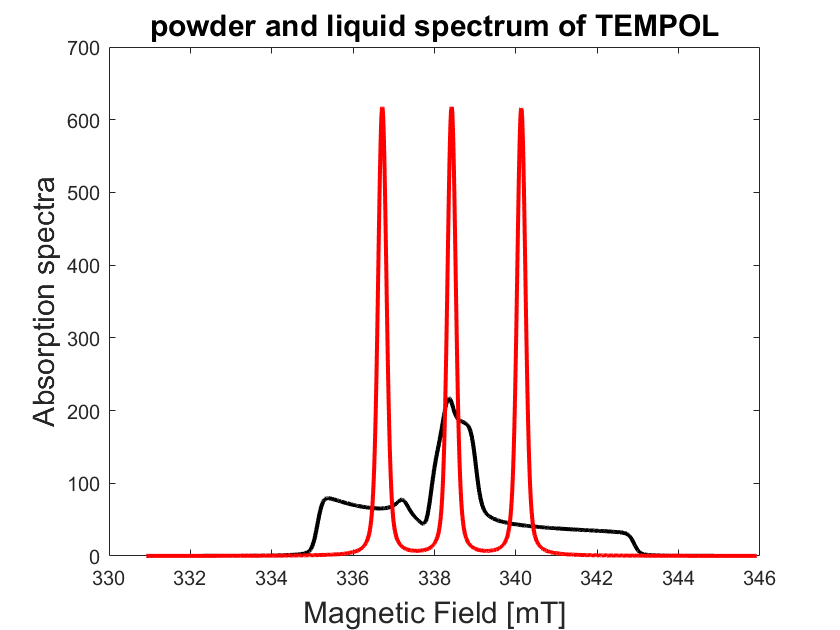

FieldRange=15;               % Field Range in mT
Exp.CenterSweep=[CenterField,FieldRange];
[B,spectrumPowder]=pepper(Sys,Exp);  
Sys.tcorr=1e-12;              % rotational correlation time in s
spectrumIsotropic=garlic(Sys,Exp);
plot(B,spectrumPowder,'k',B,spectrumIsotropic,'r','LineWidth',2)
xlabel('Magnetic Field [mT]','FontSize',15)
ylabel('Absorption spectra','FontSize',15)
title('powder and liquid spectrum of TEMPOL','FontSize',15)

Usually the first derivative is recorded in cw-EPR:

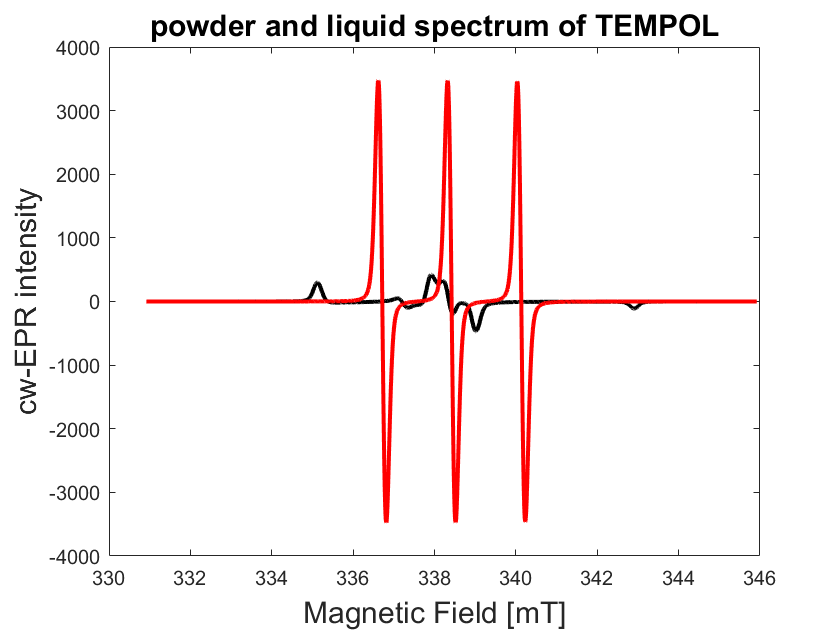

Exp.Harmonic=1;
[B,spectrumPowder]=pepper(Sys,Exp);  
Sys.tcorr=1e-12;              % rotational correlation time in s
spectrumIsotropic=garlic(Sys,Exp);
plot(B,spectrumPowder,'k',B,spectrumIsotropic,'r','LineWidth',2)
xlabel('Magnetic Field [mT]','FontSize',15)
ylabel('cw-EPR intensity','FontSize',15)
title('powder and liquid spectrum of TEMPOL','FontSize',15)